clear all
close all
%% define dei lati e dei giunti
L=[2.5 1 1.5 2.5];
Q=[0.5 1 0.5];
%% calcolo dellle matrix
[M01_ M1_1 M12 M23]=TR4_positionMat(Q,L)

M01_ =     1.0000         0         0    2.1940
         0    1.0000         0         0
         0         0    1.0000   -1.1986
         0         0         0    1.0000


M1_1 =      1     0     0     1
     0     1     0     0
     0     0     1     0
     0     0     0     1


M12 =     0.7702   -0.5950    0.2298    1.1552
    0.5950    0.5403   -0.5950    0.8925
    0.2298    0.5950    0.7702    0.3448
         0         0         0    1.0000


M23 =     0.8776         0    0.4794    2.1940
         0    1.0000         0         0
   -0.4794         0    0.8776   -1.1986
         0         0         0    1.0000


%% position of robot
S = TR4_dirKin(Q,L)

S =     5.7634
    2.9111
   -1.2726
    1.0000


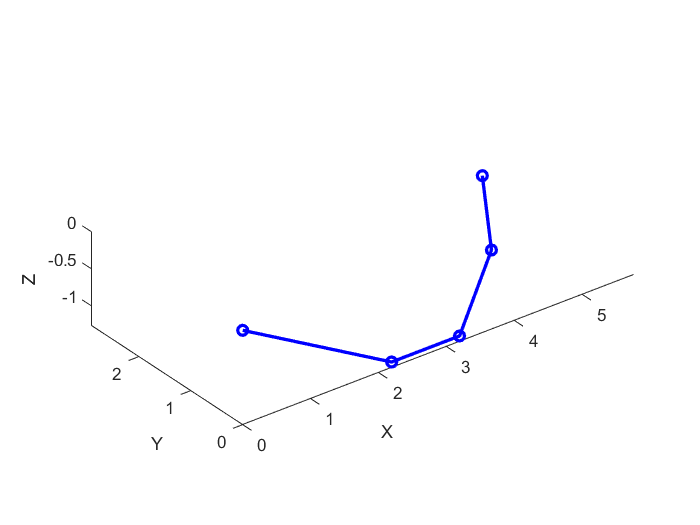

%% plot del robot
TR4_plot(Q,L,'b',1)

% definizioni variabili simboliche
Q=(sym('q', [1 3]))

$$Q = \left(\begin{array}{ccc} q_{1} & q_{2} & q_{3} \end{array}\right)$$

L=(sym('l', [1 4]))

$$L = \left(\begin{array}{cccc} l_{1} & l_{2} & l_{3} & l_{4} \end{array}\right)$$

%% definizione della cinematica diretta
[M01_ M1_1 M12 M23]=TR4_positionMat(Q,L)

$$M01\_ = \left(\begin{array}{cccc} 1 & 0 & 0 & l_{1}\,\cos\left(q_{1}\right)\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & -l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$M1\_1 = \left(\begin{array}{cccc} 1 & 0 & 0 & l_{2}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$M12 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{2} & \frac{1}{2}-\frac{\cos\left(q_{2}\right)}{2} & l_{3}\,\sigma_{1}\\ \sigma_{2} & \cos\left(q_{2}\right) & -\sigma_{2} & \frac{\sqrt{2}\,l_{3}\,\sin\left(q_{2}\right)}{2}\\ \frac{1}{2}-\frac{\cos\left(q_{2}\right)}{2} & \sigma_{2} & \sigma_{1} & -l_{3}\,\left(\frac{\cos\left(q_{2}\right)}{2}-\frac{1}{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\cos\left(q_{2}\right)}{2}+\frac{1}{2}\\ \sigma_{2}=\frac{\sqrt{2}\,\sin\left(q_{2}\right)}{2} \end{array}$$

$$M23 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & 0 & \sin\left(q_{3}\right) & l_{4}\,\cos\left(q_{3}\right)\\ 0 & 1 & 0 & 0\\ -\sin\left(q_{3}\right) & 0 & \cos\left(q_{3}\right) & -l_{4}\,\sin\left(q_{3}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

M01=M01_*M1_1

$$M01 = \left(\begin{array}{cccc} 1 & 0 & 0 & l_{2}+l_{1}\,\cos\left(q_{1}\right)\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & -l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

M02=M01*M12

$$M02 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{2} & \frac{1}{2}-\frac{\cos\left(q_{2}\right)}{2} & l_{2}+l_{3}\,\sigma_{1}+l_{1}\,\cos\left(q_{1}\right)\\ \sigma_{2} & \cos\left(q_{2}\right) & -\sigma_{2} & \frac{\sqrt{2}\,l_{3}\,\sin\left(q_{2}\right)}{2}\\ \frac{1}{2}-\frac{\cos\left(q_{2}\right)}{2} & \sigma_{2} & \sigma_{1} & -l_{3}\,\left(\frac{\cos\left(q_{2}\right)}{2}-\frac{1}{2}\right)-l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\cos\left(q_{2}\right)}{2}+\frac{1}{2}\\ \sigma_{2}=\frac{\sqrt{2}\,\sin\left(q_{2}\right)}{2} \end{array}$$

M03=M02*M23

$$M03 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(q_{3}\right)\,\sigma_{2}+\sin\left(q_{3}\right)\,\sigma_{1} & -\sigma_{5} & \sin\left(q_{3}\right)\,\sigma_{2}-\cos\left(q_{3}\right)\,\sigma_{1} & l_{2}+l_{3}\,\sigma_{2}+l_{1}\,\cos\left(q_{1}\right)+l_{4}\,\cos\left(q_{3}\right)\,\sigma_{2}+l_{4}\,\sin\left(q_{3}\right)\,\sigma_{1}\\ \sigma_{4}+\sigma_{3} & \cos\left(q_{2}\right) & \sigma_{3}-\sigma_{4} & \frac{\sqrt{2}\,l_{3}\,\sin\left(q_{2}\right)}{2}+\frac{\sqrt{2}\,l_{4}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)}{2}+\frac{\sqrt{2}\,l_{4}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)}{2}\\ -\cos\left(q_{3}\right)\,\sigma_{1}-\sin\left(q_{3}\right)\,\sigma_{2} & \sigma_{5} & \cos\left(q_{3}\right)\,\sigma_{2}-\sin\left(q_{3}\right)\,\sigma_{1} & -l_{3}\,\sigma_{1}-l_{1}\,\sin\left(q_{1}\right)-l_{4}\,\cos\left(q_{3}\right)\,\sigma_{1}-l_{4}\,\sin\left(q_{3}\right)\,\sigma_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\cos\left(q_{2}\right)}{2}-\frac{1}{2}\\ \sigma_{2}=\frac{\cos\left(q_{2}\right)}{2}+\frac{1}{2}\\ \sigma_{3}=\frac{\sqrt{2}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)}{2}\\ \sigma_{4}=\frac{\sqrt{2}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)}{2}\\ \sigma_{5}=\frac{\sqrt{2}\,\sin\left(q_{2}\right)}{2} \end{array}$$

Sg = M03*[0 0 0 1]'

$$Sg = \begin{array}{l} \left(\begin{array}{c} l_{2}+l_{3}\,\sigma_{2}+l_{1}\,\cos\left(q_{1}\right)+l_{4}\,\cos\left(q_{3}\right)\,\sigma_{2}+l_{4}\,\sin\left(q_{3}\right)\,\sigma_{1}\\ \frac{\sqrt{2}\,l_{3}\,\sin\left(q_{2}\right)}{2}+\frac{\sqrt{2}\,l_{4}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)}{2}+\frac{\sqrt{2}\,l_{4}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)}{2}\\ -l_{3}\,\sigma_{1}-l_{1}\,\sin\left(q_{1}\right)-l_{4}\,\cos\left(q_{3}\right)\,\sigma_{1}-l_{4}\,\sin\left(q_{3}\right)\,\sigma_{2}\\ 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\cos\left(q_{2}\right)}{2}-\frac{1}{2}\\ \sigma_{2}=\frac{\cos\left(q_{2}\right)}{2}+\frac{1}{2} \end{array}$$

%% calcolo jacobiana
J = jacobian(Sg(1:end-1),Q)

$$J = \begin{array}{l} \left(\begin{array}{ccc} -l_{1}\,\sin\left(q_{1}\right) & -\sigma_{5}-\sigma_{2}-\sigma_{1} & l_{4}\,\cos\left(q_{3}\right)\,\sigma_{3}-l_{4}\,\sin\left(q_{3}\right)\,\sigma_{4}\\ 0 & \frac{\sqrt{2}\,l_{3}\,\cos\left(q_{2}\right)}{2}+\frac{\sqrt{2}\,l_{4}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)}{2}+\frac{\sqrt{2}\,l_{4}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)}{2} & \frac{\sqrt{2}\,l_{4}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)}{2}-\frac{\sqrt{2}\,l_{4}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)}{2}\\ -l_{1}\,\cos\left(q_{1}\right) & \sigma_{5}+\sigma_{2}+\sigma_{1} & l_{4}\,\sin\left(q_{3}\right)\,\sigma_{3}-l_{4}\,\cos\left(q_{3}\right)\,\sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{l_{4}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)}{2}\\ \sigma_{2}=\frac{l_{4}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)}{2}\\ \sigma_{3}=\frac{\cos\left(q_{2}\right)}{2}-\frac{1}{2}\\ \sigma_{4}=\frac{\cos\left(q_{2}\right)}{2}+\frac{1}{2}\\ \sigma_{5}=\frac{l_{3}\,\sin\left(q_{2}\right)}{2} \end{array}$$

J = matlabFunction(J)%conbversione in matlab function to use it

J = function_handle with value:
    @(l1,l3,l4,q1,q2,q3)reshape([-l1.*sin(q1),0.0,-l1.*cos(q1),l3.*sin(q2).*(-1.0./2.0)-(l4.*cos(q3).*sin(q2))./2.0-(l4.*sin(q2).*sin(q3))./2.0,(sqrt(2.0).*l3.*cos(q2))./2.0+(sqrt(2.0).*l4.*cos(q2).*cos(q3))./2.0+(sqrt(2.0).*l4.*cos(q2).*sin(q3))./2.0,(l3.*sin(q2))./2.0+(l4.*cos(q3).*sin(q2))./2.0+(l4.*sin(q2).*sin(q3))./2.0,l4.*cos(q3).*(cos(q2)./2.0-1.0./2.0)-l4.*sin(q3).*(cos(q2)./2.0+1.0./2.0),(sqrt(2.0).*l4.*cos(q3).*sin(q2))./2.0-(sqrt(2.0).*l4.*sin(q2).*sin(q3))./2.0,-l4.*cos(q3).*(cos(q2)./2.0+1.0./2.0)+l4.*sin(q3).*(cos(q2)./2.0-1.0./2.0)],[3,3])


J_=JacRobot(Q,L)

Unrecognized function or variable 'JacRobot'.

Q=TR4_invNumeric([4 1 1],Q,L,100)
S=DirectRobot(Q,L)

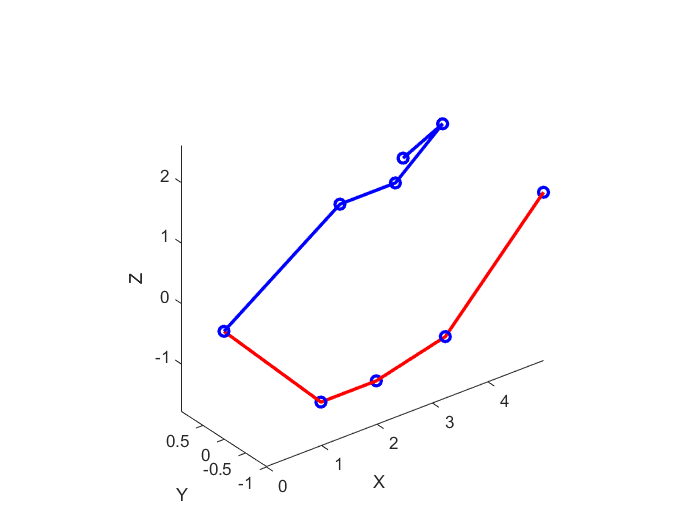

close all
clear all

L=[2.5 1 1.5 2.5];
Si=[4 1 1];
Sf=[5 -1 1];
Qi=TR4_invNumeric(Si,[0.5 0.5 0.5],L,50);
Qf=TR4_invNumeric(Sf,[0.5 0.5 0.5],L,50);
TR4_plot(Qi,L,'b',1)
TR4_plot(Qf,L,'r',1)
hold on

[Q,T,X]=TR4_linearMov([Si' Sf'],@Cicloidale,5,L);

ans = 2

Error using  ' 
TRANSPOSE does not support N-D arrays. Use PAGETRANSPOSE/PAGECTRANSPOSE to transpose pages or PERMUTE to reorder dimensions of N-D arrays.

Error in TR4_linearMov (line 21)
        Qi=Q(i,find(T==t),:)';

plot3(X(1,:,1),X(1,:,2),X(1,:,3))
figure
plot(T(1,:),Q(:,:,1),T(1,:),Q(:,:,2),T(1,:),Q(:,:,3))

figure
Jy1=0.427;Jz1=Jy1;Jg1=Jz1;
Jy2=0.286;Jz2=Jy2;Jg2=Jy2;
Jy3=0.0533;Jz3=Jy3;Jg3=Jz3;
g1=0.48;g2=0.42;g3=0.24;
m1=8;m2=7;m3=4;
Jx1=0;Jx2=Jx1;Jx3=Jx1;
Jxy=0;Jxz=0;Jyz=0;

J1_1=calcJ(Jx1,Jy1,Jz1,Jxy,Jyz,Jxz,m1,[L(2) 0 0],[g1 0 0]);
J2_2=calcJ(Jx2,Jy2,Jz2,Jxy,Jyz,Jxz,m2,[L(3) 0 0],[g2 0 0]);
J3_3=calcJ(Jx3,Jy3,Jz3,Jxy,Jyz,Jxz,m3,[L(4) 0 0],[g3 0 0]);

T = 5;
n= 100;
St = [];
Vt = [];
At = [];
Sp=[];
F3=[];
F2=[];
F1=[];
tt = zeros(0,100);


Lrz = [0 -1 0 0;
    1  0 0 0;
    0  0 0 0;
    0  0 0 0];

Lry = -[0  0 1 0;
    0  0 0 0;
    -1  0 0 0;
    0  0 0 0];
Hg=[0 0 0 0;
    0 0 0 0;
    0 0 0 -9.81;
    0 0 0 0];


for i = 1:n
    f=[0 0 0 1;
        0 0 0 1;
        0 0 0 1;
        -1 -1 -1 0];
    t=(i-1)*T/(n-1); % time from 0 to T with step dT
    tt(i) = t;
    t=2.3667;
    [Q1(i),Q1p(i),Q1pp(i)] = Cicloidale(t,T,Qi(1),Qf(1)-Qi(1));
    [Q2(i),Q2p(i),Q2pp(i)] = Cicloidale(t,T,Qi(2),Qf(2)-Qi(2));
    [Q3(i),Q3p(i),Q3pp(i)] = Cicloidale(t,T,Qi(3),Qf(3)-Qi(3));
    
    Q = [Q1(i),Q2(i),Q3(i)];
    Qp = [Q1p(i),Q2p(i),Q3p(i)];
    Qpp = [Q1pp(i),Q2pp(i),Q3pp(i)];
    
    [M01,M12,M23,M03] = matrixRRR(Q,L);
    s = M03(:,4);
    St = [St s];
    
    M02 = M01*M12;
    
    w01_0 = Lrz*Qp(1); %speed in 0-1 referece system 0
    w12_0 = M01*Lrz*Qp(2)*inv(M01); %speed in 1-2 referece system 0
    w23_0 = M02*Lry*Qp(3)*inv(M02); %speed in 2-3 the referece system 0

    w02_0 = w01_0 + w12_0; %speed in 0-2 referece system 0 (sum 0-1 % 1-2)
    w03_0 = w02_0 + w23_0; %speed in 0-3 referece system 0 (sum 0-2 % 2-3) gripper velocity seen by 0

    sp = w03_0*s;
    Sp = [Sp sp];

    h01_0 = (Lrz*Qpp(1) + Lrz^2*Qp(1)^2); %acceleration in 0-1 referece system 0
    h12_0 = M01*(Lrz*Qpp(2) + Lrz^2*Qp(2)^2)*inv(M01); %acceleration in 1-2 referece system 0
    h23_0 = M02*(Lry*Qpp(3) + Lry^2*Qp(3)^2)*inv(M02); %acceleration in 2-3 referece system 0

    h02_0 = h01_0 + h12_0 + 2*w01_0*w12_0; %acc in 0-2 referece system 0 (sum 0-1 % 1-2 and coriolis between them)
    h03_0 = h02_0 + h23_0 + 2*w02_0*w23_0; %acc in 0-3 referece system 0 (sum 0-2 % 2-3 and coriolis between them)
    Vt = [Vt w03_0*s];
    At = [At h03_0*s];
    J01_0=M01*J1_1*M01';
    J02_0=M02*J2_2*M02';
    J03_0=M03*J3_3*M03';    
    
    F3=[F3 skew(h03_0*J03_0)-skew(Hg*J03_0)+f];
    F2=[F2 skew(h02_0*J02_0)-skew(Hg*J02_0)+F3(end)];
    F1=[F1 skew(h01_0*J01_0)-skew(Hg*J01_0)+F2(end)];
    
end
hold on
plot3(St(1,:),St(2,:),St(3,:),"LineWidth",3,"Color",'g')
figure()
plot(tt,St(1,:),tt,St(2,:),tt,St(3,:))
legend("x","y","z")
figure()
plot(tt,Vt(1,:),tt,Vt(2,:),tt,Vt(3,:))
legend("x","y","z")
figure()
ATN1=diff(Vt(1,:))/(tt(2)-tt(1));
ATN2=diff(Vt(2,:))/(tt(2)-tt(1));
ATN3=diff(Vt(3,:))/(tt(2)-tt(1));
plot(tt,At(1,:),tt,At(2,:),tt,At(3,:))
hold on
plot(tt(1:end-1),ATN1,tt(1:end-1),ATN2,tt(1:end-1),ATN3)
legend("x","y","z","x diff","y diff","z diff")
